# **Project Topic - Digital Hearing Aid System**

#### Group No. 2

#### Batch - A4

#### Team Members:

####     3166 - Vaishnavi P. Mane

####     3167 - Vaishnavi R. Mane

####     3168 - Aishwarya Anil Menon

####     3173 - Gauri Balsing

clc
clf
clear
close all

#### Input Audio Signal

In-built sound track playing...


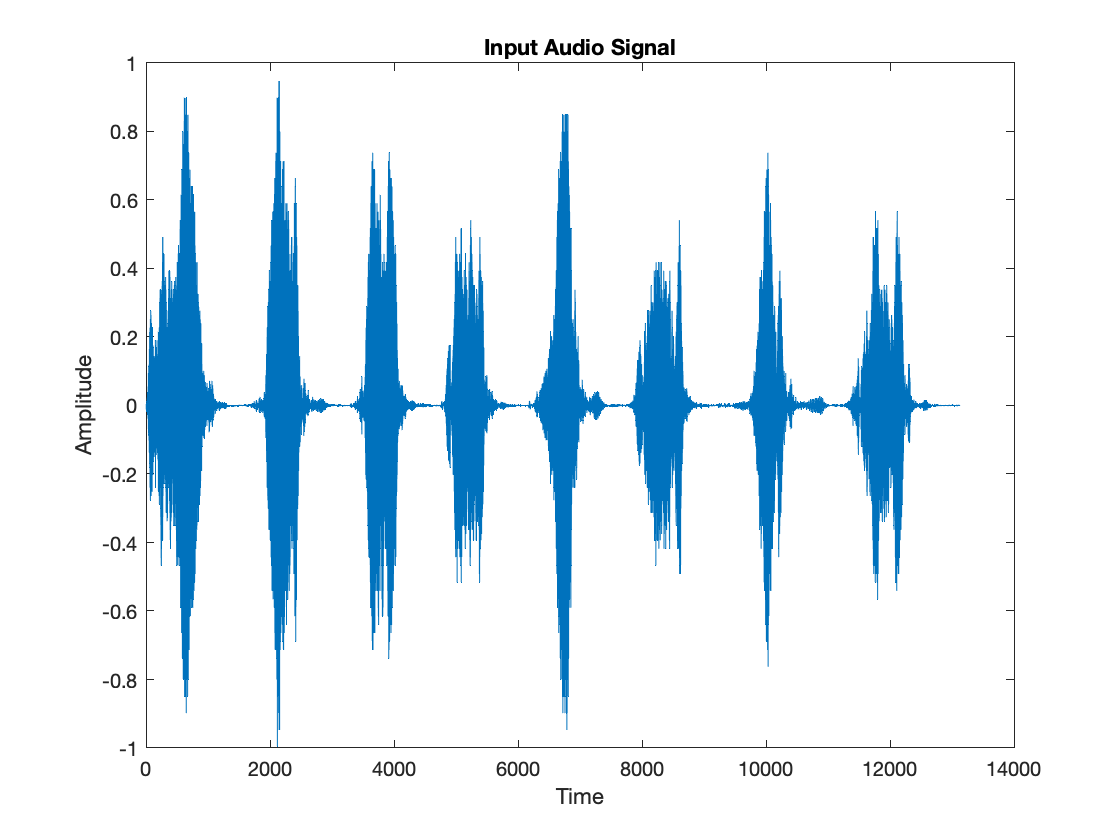

The sampling frequency of the signal:


        8192



promptMessage = sprintf('Would you like to record your own audio for further processing?');
titleBarCaption = 'Record Sound';
button = questdlg(promptMessage, titleBarCaption, 'Yes', 'No', 'Yes');
if strcmpi(button, 'Yes')

    recObj = audiorecorder;
    recDuration = 5;
    disp('Start Speaking');
    recordblocking(recObj, recDuration);
    disp('End recording');
    disp('Playing Recorded Audio...');

    y = getaudiodata(recObj);
    figure,plot(y);
    title('Input Audio Signal');
    xlabel('Time');
    ylabel('Amplitude');

    fs = 8000;  %standard speech signal sampling frequency
    play(recObj);
    %pause(10);

else 

    disp('In-built sound track playing...')
    load chirp.mat  %Pre-defined matlab audio

    figure,plot(y);
    title('Input Audio Signal');
    xlabel('Time');
    ylabel('Amplitude');

    fs=Fs;
    disp('The sampling frequency of the signal:');
    disp(fs);
    %y = y(:, 1);

    sound(y);
    pause(5);

end

#### Adding Noise to the Audio Signal

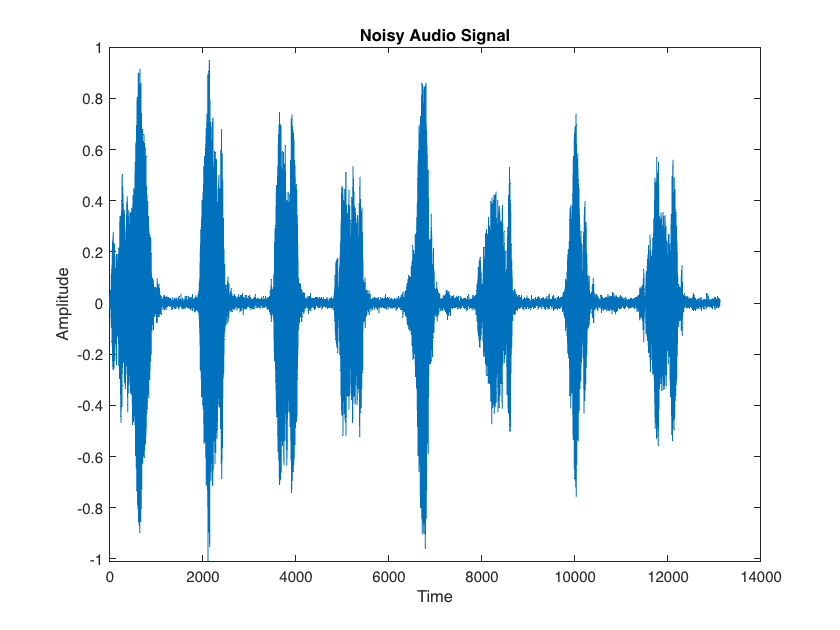

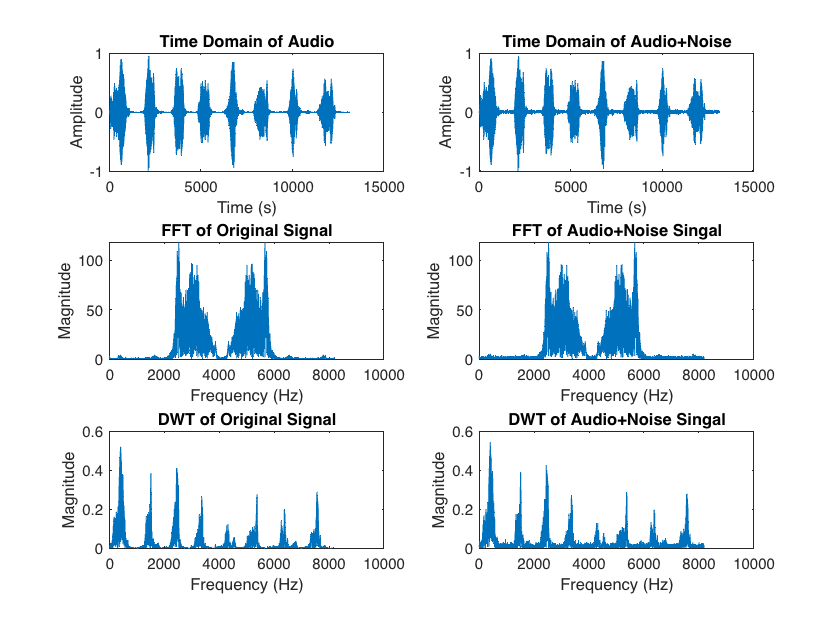

promptMessage = sprintf('Do you want me to add noise to the audio file?');
titleBarCaption = 'Adding Noise';
button = questdlg(promptMessage, titleBarCaption, 'Yes', 'No', 'Yes');
if strcmpi(button, 'Yes')
    noi = awgn(y,40);
    sound(noi);
    figure,plot(noi);
    title('Noisy Audio Signal');
    xlabel('Time');
    ylabel('Amplitude');


    y_fft = fft(y);
    fy = (0:length(y_fft)-1)*fs/length(y_fft);

    noi_fft = fft(noi);
    fnoi = (0:length(noi_fft)-1)*fs/length(noi_fft);
    
    [cy1, cy2] = dwt(y,'sym4');
    fy2 = (0:length(cy1)-1)*fs/length(cy1);

    [cnoi1, cnoi2] = dwt(noi,'sym4');
    fnoi2 = (0:length(cnoi1)-1)*fs/length(cnoi1);

    figure
    subplot(3,2,1);
    plot(y);
    xlabel('Time (s)')
    ylabel('Amplitude')
    title('Time Domain of Audio')

    subplot(3,2,2);
    plot(noi);
    xlabel('Time (s)')
    ylabel('Amplitude')
    title('Time Domain of Audio+Noise')

    subplot(3,2,3);
    plot(fy, abs(y_fft));
    xlabel('Frequency (Hz)')
    ylabel('Magnitude')
    title('FFT of Original Signal')

    subplot(3,2,4);
    plot(fnoi,abs(noi_fft));
    xlabel('Frequency (Hz)')
    ylabel('Magnitude')
    title('FFT of Audio+Noise Singal')

    subplot(3,2,5);
    plot(fy2,abs(cy1));
    xlabel('Frequency (Hz)')
    ylabel('Magnitude')
    title('DWT of Original Signal')

    subplot(3,2,6);
    plot(fnoi2,abs(cnoi1));
    xlabel('Frequency (Hz)')
    ylabel('Magnitude')
    title('DWT of Audio+Noise Singal')
   
else
    noi = y;
end

#### Denoising the Audio Signal

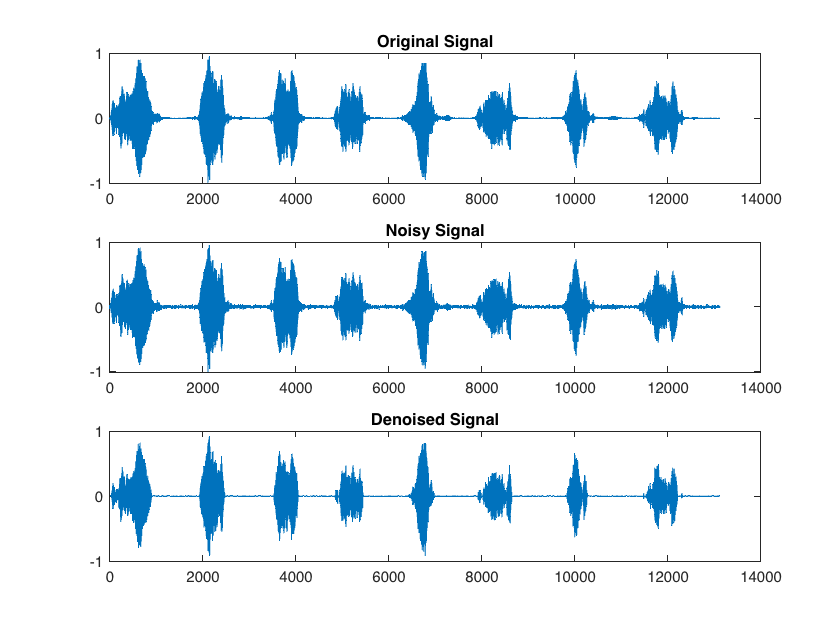

promptMessage = sprintf('Would you like to recover the original signal?');
titleBarCaption = 'Denoise the Noisy Signal';
button = questdlg(promptMessage, titleBarCaption, 'Yes', 'No', 'Yes');
if strcmpi(button, 'Yes')
    [thr,sorh,keepapp] = ddencmp('den','wv',noi);
    denoi = wdencmp('gbl',noi,'sym4',5,thr,sorh,keepapp);

    figure
    subplot(3,1,1);
    plot(y);
    title('Original Signal')
    subplot(3,1,2);
    plot(noi);
    title('Noisy Signal')
    subplot(3,1,3);
    plot(denoi);
    title('Denoised Signal')

    sound(denoi);
else
end

#### Wavelet Comparison (with FIR & IIR)

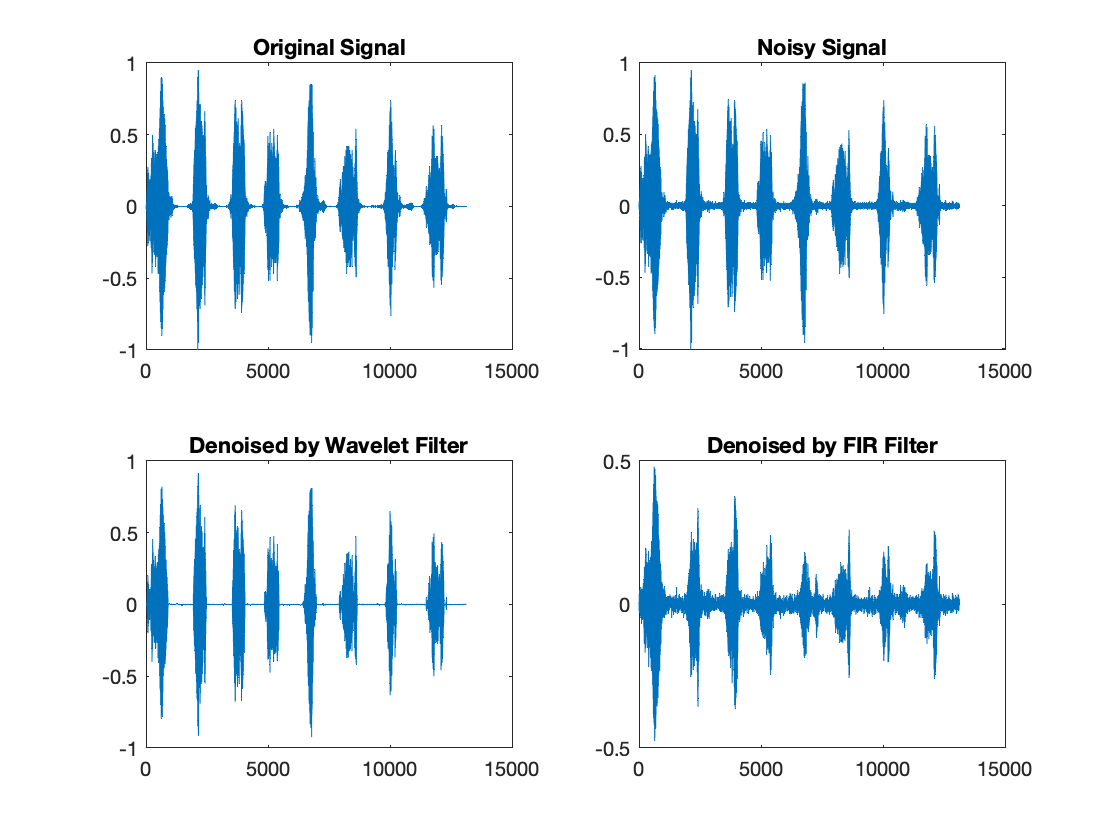

PlayAgain = true;
while PlayAgain
    promptMessage = sprintf('With what would you like to compare the Wavelet Filter?');
    titleBarCaption = 'Comparison of Wavelet, FIR & IIR Filters';
    button = questdlg(promptMessage, titleBarCaption, 'FIR', 'IIR', 'FIR');
    if strcmpi(button, 'FIR')
        promptMessage = sprintf('Choose one FIR Filter.');
        titleBarCaption = 'Wavelet vs. FIR';
        button = questdlg(promptMessage, titleBarCaption, 'Hamming', 'Hanning', 'Hamming');
        if strcmpi(button, 'Hamming')
            Whamm = hamming(5);
            FIR_denoi = filter(Whamm, 1, noi);
    
        else
            Whan = hanning(5);
            FIR_denoi = filter(Whan, 1, noi);
    
        end
    
        figure
        subplot(2,2,1);
        plot(y);
        title('Original Signal')
        subplot(2,2,2);
        plot(noi);
        title('Noisy Signal')
        subplot(2,2,3);
        plot(denoi);
        title('Denoised by Wavelet Filter')
        subplot(2,2,4);
        plot(FIR_denoi);
        title('Denoised by FIR Filter')
    
        sound(FIR_denoi);
    
    else
        promptMessage = sprintf('Choose one IIR Filter.');
        titleBarCaption = 'Wavelet vs. IIR';
        button = questdlg(promptMessage, titleBarCaption, 'Butterworth', 'Chebyshev', 'Butterworth');
        if strcmpi(button, 'Butterworth')
            n = 5; %order of filter
            %Wn = (700*2)/8000;
            Wn = 0.6;
            [b,a] = butter(n,Wn);
            %figure, freqz(b,a,1024,8000);
            IIR_denoi = filter(b,a,noi);
    
        else
            n = 5;
            %Wp = 2000*2/8000;
            Wp = 0.7;
            Rp = 0.5;
            [b,a] = cheby1(n,Rp,Wp);
            %figure, freqz(b,a,1024,8000);
            IIR_denoi = filter(b,a,noi);
    
        end
    
            figure
            subplot(2,2,1);
            plot(y);
            title('Original Signal')
            subplot(2,2,2);
            plot(noi);
            title('Noisy Signal')
            subplot(2,2,3);
            plot(denoi);
            title('Denoised by Wavelet Filter')
            subplot(2,2,4);
            plot(IIR_denoi);
            title('Denoised by IIR Filter')
    
            sound(IIR_denoi);
    
    end
    promptMessage = sprintf('Do you want to compare with any other filter?');
    titleBarCaption = 'Continue?';
    button = questdlg(promptMessage, titleBarCaption, 'Yes', 'No', 'Yes');
    if strcmpi(button, 'No')
        playAgain = false;
        break;
    else
        playAgain = true;
    end
end

#### Amplify the Signal (using Frequency and Amplitude Shaper)

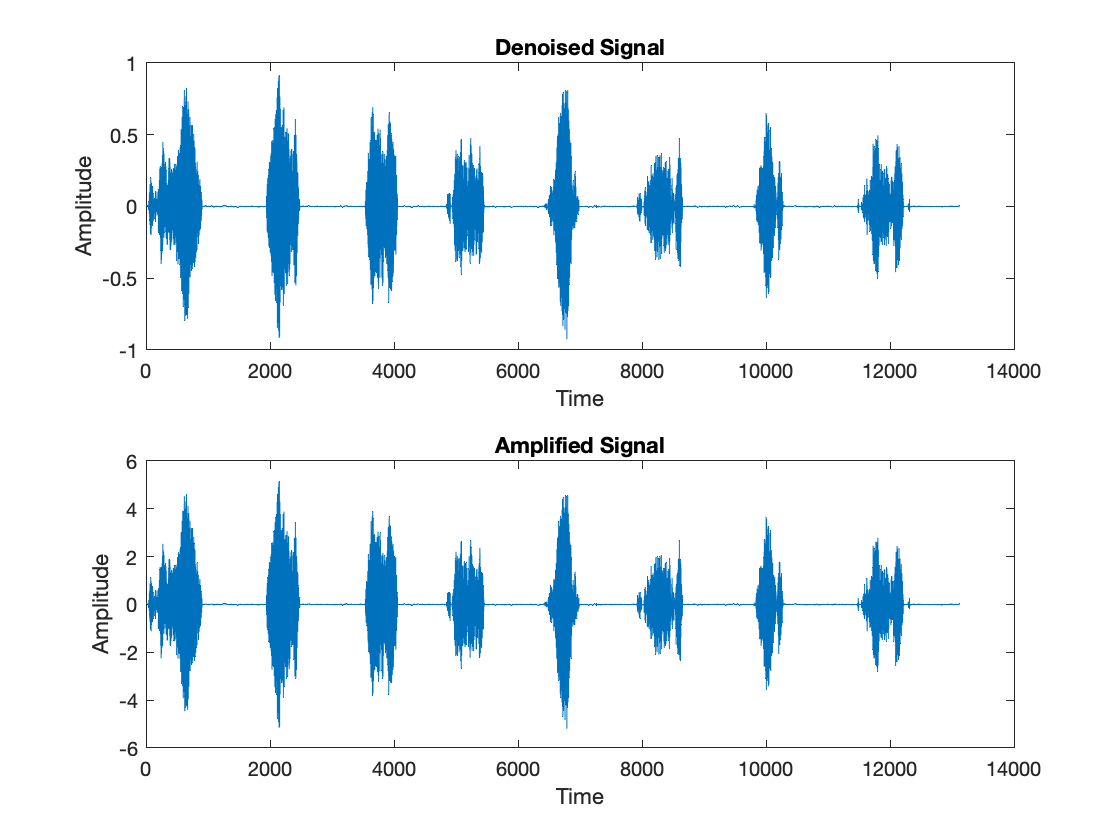

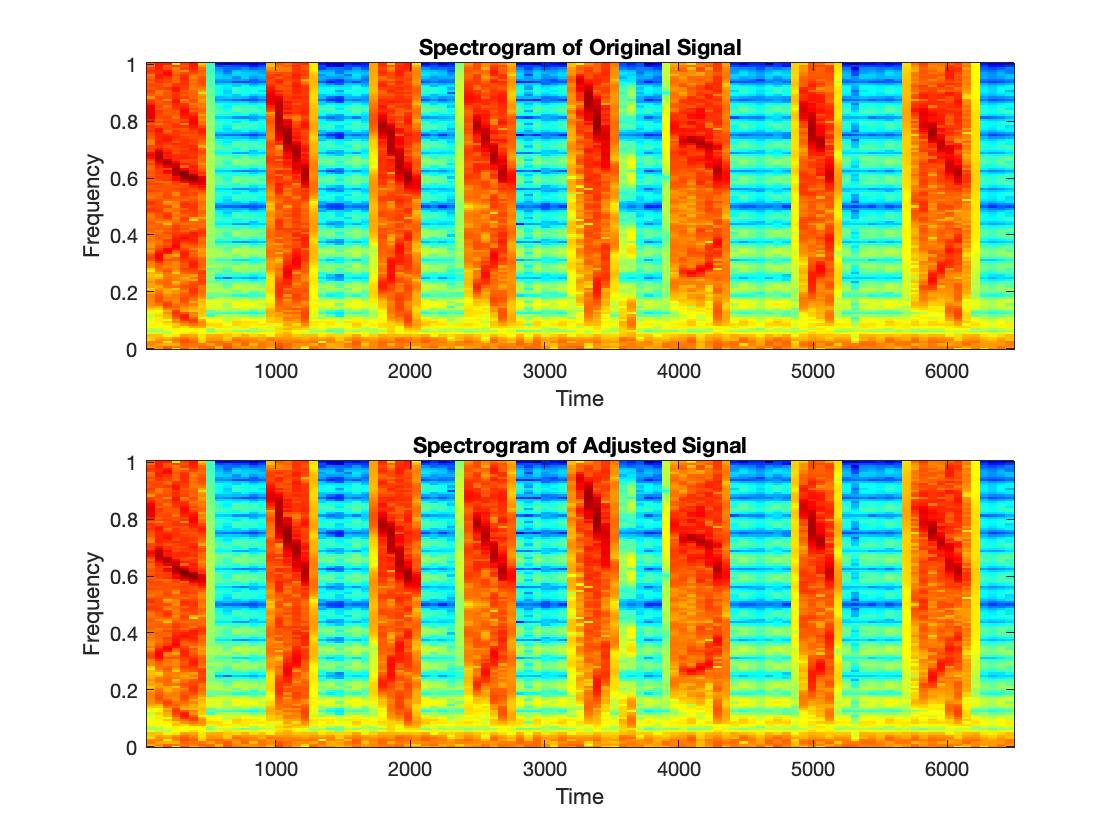

amplifyAgain = true;
while amplifyAgain
    promptMessage = sprintf('Do you want to amplify the signal?');
    titleBarCaption = 'Amplify Signal';
    button = questdlg(promptMessage, titleBarCaption, 'Yes', 'No', 'Yes');
    if strcmpi(button, 'Yes')
        promptMessage = sprintf('For whom do you want to amplify the signal?');
        titleBarCaption = 'Frequency & Amplitude Shaping';
        button = questdlg(promptMessage, titleBarCaption, 'For Hearing Impaired ppl', 'For Normal Person', 'For Hearing Impaired ppl');
    
        if strcmpi(button, 'For Hearing Impaired ppl')
            % freq shaper using bandpass
  
            T = 1/fs;
            len = length(denoi);
            disp(len);
            
            p = log2(len);
            p = ceil(p);
            N = 2^p;
            disp(N);
            
            f1 = fdesign.bandpass('Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2', 2000,3000,4000,5000,60,2,60,2*fs);
            
            hd = design(f1);
            yfinal = filter(hd, denoi);
            freqz(hd);
            yfinal = yfinal*100;
            
            disp('playing frequency shaped...');
            sound(yfinal,fs);
            pause(10);
    
            % amplitude compression
    
            disp('amplitude compression')
            out1=fft(yfinal);
            %[out1, out2] = dwt(yfinal,'sym4');
            phase=angle(out1);
            mag=abs(out1)/N;
            plot(mag);
            [magsig,~]=size(mag);
            disp(magsig);
            threshold=1000;
            out=zeros(magsig,1);
            
            for i=1:magsig/2
            
                if(mag(i)>threshold)
	                mag(i)=threshold;
                    mag(magsig-i)=threshold;
                end
                out(i)=mag(i)*exp(j*phase(i));
                out(magsig-i)=out(i);
            end
            
            %out_idwt = idwt(out1,out2,'sym4');
            %outfinal = real(out_idwt(out))*1000;
            outfinal=real(ifft(out))*10000;

            disp('playing amplitude shaped...');
            sound(outfinal,fs);
            pause(10);
    
        else
    
            promptMessage = sprintf('By how much do you want to amplify the signal?');
            %titleBarCaption = 'Amplification Value';
            answer = inputdlg(promptMessage);
            dB = str2double(answer);
    
            convertFromDb = 10^(dB/20);
            outfinal = denoi * convertFromDb;

            figure
            subplot(2,1,1);
            plot(denoi);
            xlabel('Time')
            ylabel('Amplitude')
            title('Denoised Signal')

            subplot(2,1,2);
            plot(outfinal);
            xlabel('Time')
            ylabel('Amplitude')
            title('Amplified Signal')

            sound(outfinal,fs);
    
        end
        figure;
        subplot(2,1,1);
        specgram(denoi);
        title('Spectrogram of Original Signal');
        
        subplot(2,1,2);
        specgram(outfinal);
        title('Spectrogram of Adjusted Signal');
    
    else
    end

    promptMessage = sprintf('Do you wish to amplify the signal again?');
    titleBarCaption = 'Continue?';
    button = questdlg(promptMessage, titleBarCaption, 'Yes', 'No', 'Yes');
    if strcmpi(button, 'No')
        amplifyAgain = false;
        break;
    else
        amplifyAgain = true;
    end
end